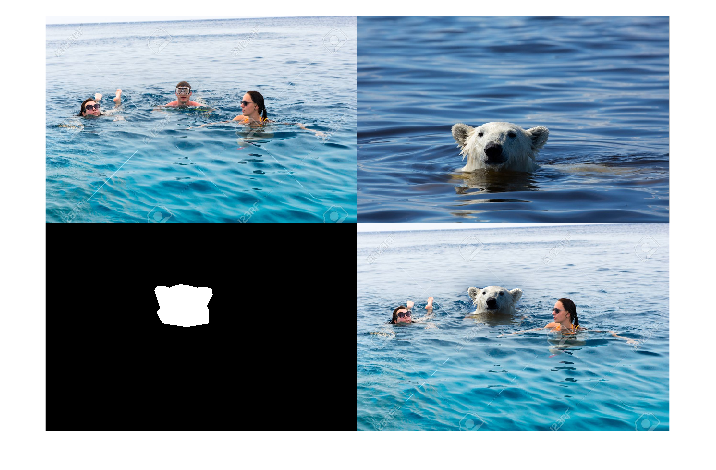

close('all');   % close all open figures so we start with a clean slate!

im_bg = im2double(imread('swim.jpg'));        % background image
im_obj = im2double(imread('bear.jpg'));       % source image

poly_x = [276.4628  324.9961  391.5884  425.4488  453.6659  457.0519  433.3496 442.3791 ...
    441.2504  348.6984  248.2457  222.2860  238.0876  226.8008  222.2860  214.3853  224.5434  248.2457];
poly_y = [255.3512  238.4209  255.3512  250.8364  260.9946  283.5682  329.8442  349.0318 ...
    404.3372  419.0101  404.3372  356.9326  342.2597  308.3992  292.5977  265.5093  250.8364  247.4504];
objmask = poly2mask(poly_x, poly_y, size(im_obj, 1), size(im_obj, 2));

center_x = 575.9264;
bottom_y = 432.4922;
padding = 64;
[im_s, mask_s] = alignSource(im_obj, objmask, im_bg, center_x, bottom_y, padding);
mask_s = im2double(mask_s);

% Call the function to blend the images using the mask
levels = 6;         % levels in the Laplacian pyramid
result1 = laplacian_blend(im_bg, im_s, mask_s, levels);

% Display:  target image, source image, mask, then blended result
figure; montage({im_bg, im_obj, mask_s, result1});

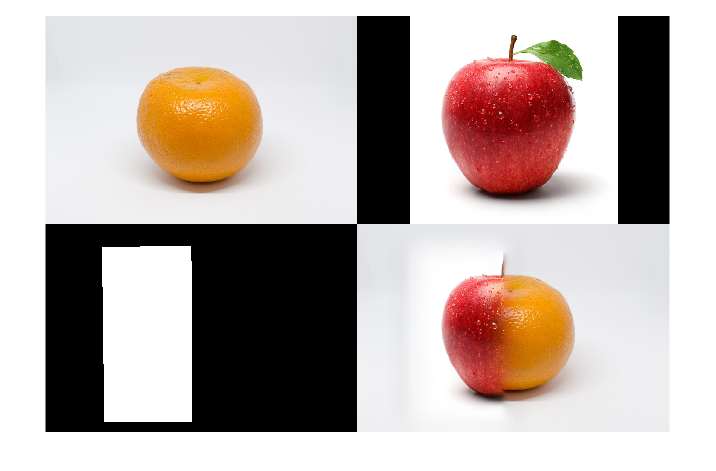



%%
% -------------------------------------------------------------------------
% IMPORTANT NOTE (please read carefully)
% -------------------------------------------------------------------------
% You must use the same images and mask and alignment coordinates as Part 1.
% Simply copy most of the code from Part 1 here.  The only difference
% is that the blending function called is now alpha_blend() instead of
% cut_and_paste().
% -------------------------------------------------------------------------


%%%%% your own images
im_obj = im2double(imread('https://media.istockphoto.com/photos/red-apple-with-droplet-picture-id185071735?b=1&k=20&m=185071735&s=612x612&w=0&h=k33ekVfdDZPH9hGZoBDbX0fu2GyyKJpluU1vqXS1qIk='));        % background image
im_bg = im2double(imread('https://upload.wikimedia.org/wikipedia/commons/thumb/9/9e/Single_Orange_%28Fruit%29.jpg/1200px-Single_Orange_%28Fruit%29.jpg'));       % source image
im_obj = imresize(im_obj,0.93);
im_bg = imresize(im_bg, 0.8);
poly_x =[7.1589  278.8411  280.1729   10.2534    3.5401];
poly_y =[29.1332   26.4696  575.1612  571.8045   32.0527];
objmask = poly2mask(poly_x, poly_y, size(im_obj, 1), size(im_obj, 2));
center_x = 314.3122;
bottom_y = 611.3287;
padding = 64;   % You may want to play with this parameter
[im_s, mask_s] = alignSource(im_obj, objmask, im_bg, center_x, bottom_y, padding);
mask_s = im2double(mask_s);

% % Apply your blending method
levels = 6;         % levels in the Laplacian pyramid
result2 = laplacian_blend(im_bg, im_s, mask_s, levels);

% Display:  target image, source image, mask, then blended result
figure; montage({im_bg, im_obj, mask_s, result2});

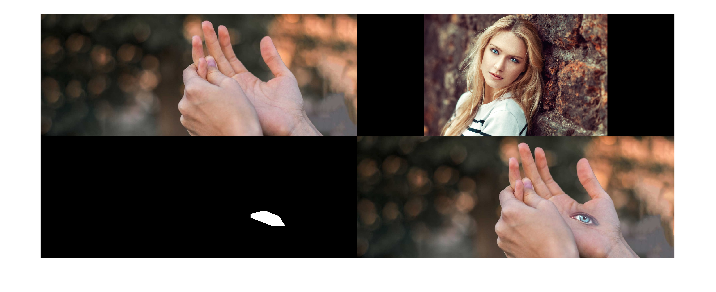



% REPEAT ABOVE FOR IMAGE SET 3
im_bg = im2double(imread('https://www.hopkinsmedicine.org/-/media/images/health/2_-treatment/orthopedics/hand-anatomy-hero.ashx?h=500&iar=0&mh=500&mw=1300&w=1297&hash=2AEC53C547082DB77E302DA3D57B4823'));        % background image
im_obj = im2double(imread('http://wallup.net/wp-content/uploads/2016/05/13/359613-women-model-looking_at_viewer-long_hair-face-blonde-blue_eyes-portrait-depth_of_field.jpg'));       % source image

poly_x =[ 934.0    990.6    1050.9    1077.3    1024.5    934.0];
poly_y = [495.3039  480.2173  502.8471  544.3352  544.3352  510.3904];

objmask = poly2mask(poly_x, poly_y, size(im_obj, 1), size(im_obj, 2));
center_x = 930.8527;
bottom_y = 368.7348;
padding = 64;   % You may want to play with this parameter
[im_s, mask_s] = alignSource(im_obj, objmask, im_bg, center_x, bottom_y, padding);
mask_s = im2double(mask_s);

% % Apply your blending method
levels = 6;         % levels in the Laplacian pyramid
result2 = laplacian_blend(im_bg, im_s, mask_s, levels);

% Display:  target image, source image, mask, then blended result
figure; montage({im_bg, im_obj, mask_s, result2});

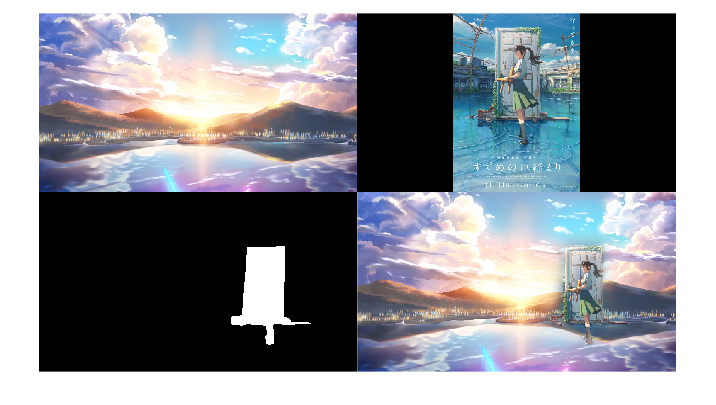


% REPEAT ABOVE FOR IMAGE SET 4
im_obj = im2double(imread('https://s.yimg.com/ny/api/res/1.2/PTbmgy0BUopOAZrscF82pQ--/YXBwaWQ9aGlnaGxhbmRlcjt3PTY0MA--/https://s.yimg.com/uu/api/res/1.2/Y93CEvkqF6YklDNaFKZANQ--~B/aD0wO3c9MDthcHBpZD15dGFjaHlvbg--/https://media.zenfs.com/zh-tw/gotv_ctitv_com_tw_678/27f01c37716dfdf4e7f9844f125625d9'));        % background image
im_bg = im2double(imread('https://macjpeg.mac89.com/macw/pic/202007/11114247_660f3cd1b7.jpeg'));       % source image

poly_x = [214.6589  439.0421  436.9252  451.7430  464.4439  472.9112  479.2617  479.2617  496.1963  576.6355  608.3879  511.0140  466.5607  415.7570  405.1729  390.3551  375.5374  371.3037  373.4206  373.4206  377.6542  377.6542  358.6028  337.4346  328.9673  328.9673  328.9673  324.7336  318.3832  331.0841  331.0841  331.0841  326.8505  314.1495  288.7477  259.1121  240.0607  210.4252  201.9579  185.0234  157.5047  127.8692  119.4019  119.4019  119.4019  134.2196  144.8037  161.7383  174.4393  182.9065];
poly_y =[75.6472   73.5304  499.0117  501.1285  505.3621  511.7126  522.2967  526.5304  526.5304  528.6472  539.2313  543.4650  547.6986  543.4650  543.4650  539.2313  539.2313  554.0491  575.2173  600.6192  632.3715  657.7734  664.1238  664.1238  659.8902  651.4229  638.7220  630.2547  617.5537  604.8528  592.1519  579.4509  549.8154  549.8154  545.5818  545.5818  545.5818  539.2313  545.5818  551.9322  545.5818  547.6986  534.9977  509.5958  499.0117  490.5444  492.6612  492.6612  488.4276  484.1939];

objmask = poly2mask(poly_x, poly_y, size(im_obj, 1), size(im_obj, 2));
center_x = 1.3601e+03;
bottom_y = 917.0746;
padding = 64;   % You may want to play with this parameter
[im_s, mask_s] = alignSource(im_obj, objmask, im_bg, center_x, bottom_y, padding);
mask_s = im2double(mask_s);

% % Apply your blending method
levels = 6;         % levels in the Laplacian pyramid
result2 = laplacian_blend(im_bg, im_s, mask_s, levels);

% Display:  target image, source image, mask, then blended result
figure; montage({im_bg, im_obj, mask_s, result2});

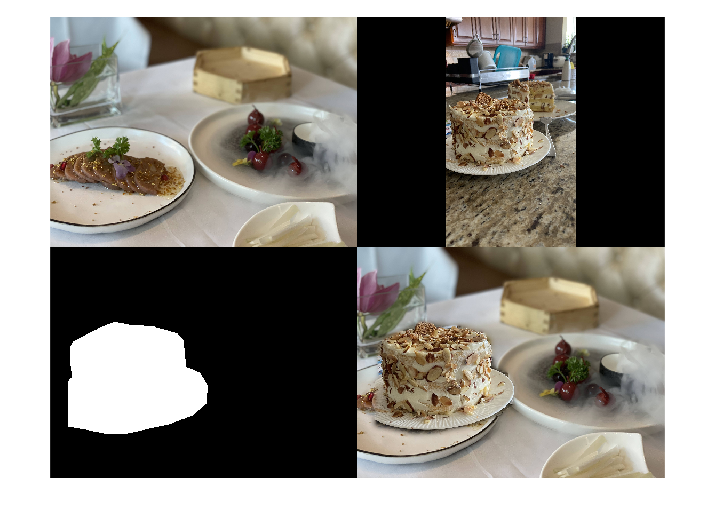


% REPEAT ABOVE FOR IMAGE SET 5
im_obj = im2double(imread('https://i.imgur.com/BuuuvEm.jpeg'));        % background image
im_bg = im2double(imread('https://imgur.com/HyYPrYw.jpg'));       % source image

poly_x = [70.0    428.0    616.4    851.9    1106.2    1436.0    1520.7    1549.0    1558.4    1737.4    1841.0    1822.2    1652.6    1332.3    776.5    531.6    220.7   -5.4   -27.2   -9.8    18.5    56.1    37.3    27.9];
poly_y = [1616.1    1427.7    1352.4    1399.5    1408.9    1503.1    1597.3    1870.5    1945.8    2021.2    2190.8    2426.3    2577.0    2699.5    2822.0    2831.4    2765.4    2727.8    2464.0    2190.8    2115.4    2077.7    1898.7    1691.5];

objmask = poly2mask(poly_x, poly_y, size(im_obj, 1), size(im_obj, 2));
center_x = 1.0660e+03;
bottom_y = 2.4518e+03;
padding = 64;   % You may want to play with this parameter
[im_s, mask_s] = alignSource(im_obj, objmask, im_bg, center_x, bottom_y, padding);
mask_s = im2double(mask_s);

% % Apply your blending method
levels = 6;         % levels in the Laplacian pyramid
result2 = laplacian_blend(im_bg, im_s, mask_s, levels);

% Display:  target image, source image, mask, then blended result
figure; montage({im_bg, im_obj, mask_s, result2});




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% These are your functions that implement the blending method
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



function im_blend = laplacian_blend(im_bg, im_s, mask_s, levels)   
    % Tip:  You may want to visualize the Gaussian and Laplacian pyramids
    % computed in this function.  Functions for displaying pyramids
    % are included below.
    pyr_bgL = pyr_laplacian(im_bg, levels);
    pyr_sL = pyr_laplacian(im_s, levels);
    pyr_mG = pyr_gaussian(mask_s, levels);
    pyr = cell([levels, 1]);
    for i=1:levels
        pyr{i} = (pyr_sL{i}.*pyr_mG{i}) + (pyr_bgL{i}.*(1-pyr_mG{i}));
    end
    im_blend = pyr_laplacian_collapse(pyr);
end


function pyr_G = pyr_gaussian(im, levels)
% Computes Gaussian pyramid of image im over number of levels
    pyr_G = cell([levels, 1]);      % declare cell array of height "levels", and width 1

    pyr_G{1} = im;                  % level 1 is the orignal image
    for i=2:levels
        pyr_G{i} = imresize(imgaussfilt(pyr_G{i-1},2), 0.5);
    end                             % level i is image at level i-1 filtered with Gaussian(2)
                                    % and then downsampled by factor of 2
end


function pyr_L = pyr_laplacian(im, levels)
% Computes Laplacian pyramid of image im over number of levels
    pyr_G = pyr_gaussian(im, levels);   % first compute the Gaussian pyramid

    pyr_L = cell([levels, 1]);      % declare cell array of height "levels", and width 1

    pyr_L{levels} = pyr_G{levels};  % top level of Laplacian pyramid is the same as that of Gaussian pyramid
    for i= (levels-1):-1:1
        [h w ~] = size(pyr_G{i});
        pyr_L{i} = pyr_G{i} - imresize(pyr_G{i+1}, [h w]);
                                    % level i of Laplacian is the difference of
                                    % Gaussian level i and upsampled level i+1
                                    % equalizes size by upsampling G{i+1}
    end
end

    
function im = pyr_laplacian_collapse(pyr)
% computes the image from its Laplacian pyramid
    levels = size(pyr, 1);
    pyr_G = cell([levels, 1]);
    pyr_G{levels} = pyr{levels};
    for i = (levels-1):-1:1
        [h w ~] = size(pyr{i});
	    pyr_G{i} = pyr{i}+imresize(pyr_G{i+1}, [h w]);
    end
    im = pyr_G{1};
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Below are complete functions to display Gaussian and
% Laplacian pyramids.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function display_gaussian(pyr)  % code is complete!
% displays the Gaussian pyramid
    figure; montage(pyr);               
end
    
function display_laplacian(pyr) % code is complete!
% displays the Laplacian pyramid
    levels = size(pyr, 1);      
    for i=1:levels-1
        pyr{i} = pyr{i} + 0.5;   % false color all levels except topmost by adding 0.5
    end
    figure; montage(pyr);
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Below are helper functions.  You DO NOT NEED TO MODIFY
% any of the code below.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [im_s2, mask2] = alignSource(im_s, mask, im_t, center_x, bottom_y, padding)
    % Inputs:  source image, mask, target/background image, ...
    % center_x, bottom_y are the coordinates of the bottom center location on the target image
    % padding is the number of extra rows/coumns to include around the
    % object to allow for feathering/blending.

    % Outputs: an aligned source image and also an aligned blending mask.
    
    % find the bounding box of the mask, and enlarge it by the amount of
    % padding
    [y, x] = find(mask);
    y1 = min(y)-1-padding; y2 = max(y)+1+padding; 
    x1 = min(x)-1-padding; x2 = max(x)+1+padding;
    im_s2 = zeros(size(im_t));

    yind = (y1:y2);
    yind2 = yind - max(y) + round(bottom_y);
    xind = (x1:x2);
    xind2 = xind - round(mean(x)) + round(center_x);
    
    % if the padding exceeds the image boundaries,
    % clip to image boundary
    yind(yind > size(im_s, 1)) = size(im_s, 1);
    yind(yind < 1) = 1;
    xind(xind > size(im_s, 2)) = size(im_s, 2);
    xind(xind < 1) = 1;
   
    yind2(yind2 > size(im_t, 1)) = size(im_t, 1);
    yind2(yind2 < 1) = 1;
    xind2(xind2 > size(im_t, 2)) = size(im_t, 2);
    xind2(xind2 < 1) = 1;

    y = y - max(y) + round(bottom_y);
    x = x - round(mean(x)) + round(center_x);
    ind = y + (x-1)*size(im_t, 1);
    mask2 = false(size(im_t, 1), size(im_t, 2));
    mask2(ind) = true;
    
    im_s2(yind2, xind2, :) = im_s(yind, xind, :);    
end
